We use the trapezoidal integration formula to compute the perimeter of an ellipse with semi-axes 1 and 1/2. Parameterizing the ellipse as $x=\cos \pi t$, $y=\frac{1}{2}\sin \pi t$ leads to the integral


$$\int_{-1}^1 \pi\sqrt{ \cos^2(\pi t) + \frac{1}{4}\sin^2(\pi t)}\,dt.$$


f = @(t) pi*sqrt( cos(pi*t).^2+sin(pi*t).^2/4 );
N = (4:4:60)';
C = zeros(size(N));
for i = 1:length(N)
    h = 2/N(i);
    t = h*(0:N(i)-1);
    C(i) = h*sum(f(t));
end
format long
perimeter = C(end)

perimeter =    4.844224110273837


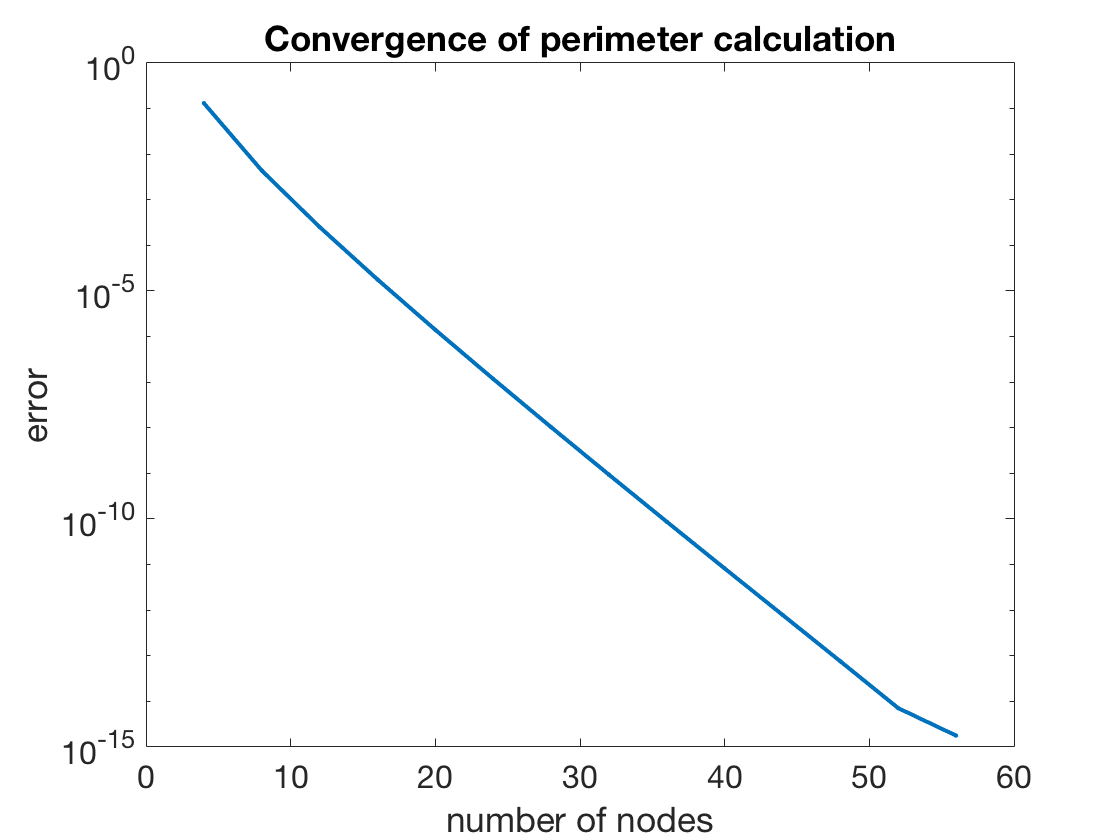

err = abs(C-C(end));
semilogy(N,err,'.-')
title('Convergence of perimeter calculation')   % ignore this line
xlabel('number of nodes'), ylabel('error')    % ignore this line

The approximations gain about one digit of accuracy for each constant increase in $N$, consistent with geometric (linear) convergence. 